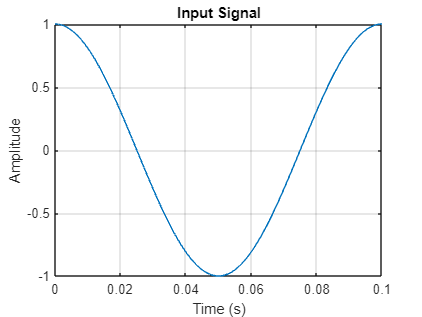

% Parameters
fm = 10;        % Message signal frequency (Hz)
Am = 1;         % Message signal amplitude
thetam = 0;     % Message signal phase angle
fs = 10000;     % Sampling frequency (Hz)
fc = 500;       % Carrier frequency (Hz)
Ac = 1;         % Carrier signal amplitude
thetac = 0;     % Carrier signal phase angle
fredev = 250;   % Frequency deviation factor
% Time vector
t = 0:1/fs:0.1; % Time scale for one time period of the message signal
% Message signal
message = Am * cos(2*pi*fm*t + thetam);

% Modulation using built-in function
modulated = fmmod(message, fc, fs, fredev);

% Demodulation using built-in function
demodulated = fmdemod(modulated, fc, fs, fredev);
% Plotting
figure;
% Input signal
plot(t, message);
xlabel('Time (s)');
ylabel('Amplitude');
title('Input Signal');
grid on;

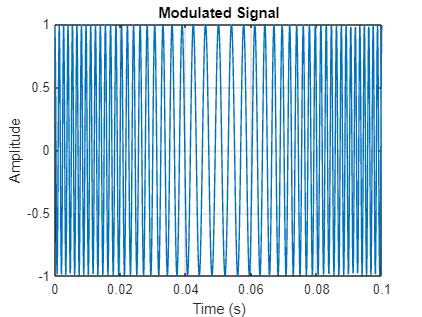

% Modulated signal
plot(t, modulated);
xlabel('Time (s)');
ylabel('Amplitude');
title('Modulated Signal');
grid on;


% Magnitude spectrum of input signal
fft_message = abs(fft(message));
frequencies = linspace(0, fs, length(fft_message));
plot(frequencies(1:length(frequencies)/2), fft_message(1:length(frequencies)/2));

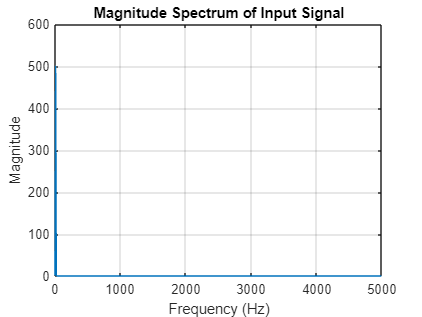

xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum of Input Signal');
grid on;

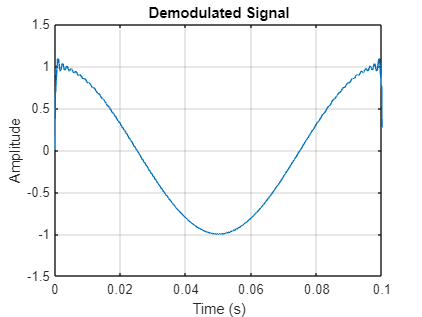



% Demodulated signal
plot(t, demodulated);
xlabel('Time (s)');
ylabel('Amplitude');
title('Demodulated Signal');
grid on;



% Magnitude spectrum of demodulated signal
fft_demodulated = abs(fft(demodulated));
plot(frequencies(1:length(frequencies)/2), fft_demodulated(1:length(frequencies)/2));

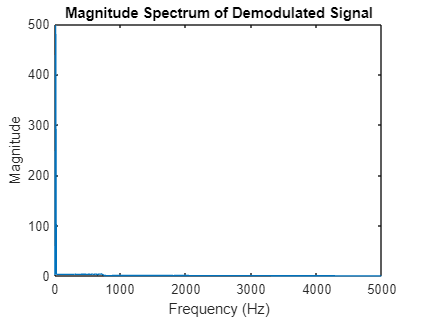

xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum of Demodulated Signal');